# Q1 Consider a network with 2 inputs, 1 hidden unit, but also with DIRECT connections from the input units to the output.  Show how such a network can conceivably compute XOR.

clear;
rs = 0; % set random seed
q1.smat = [0 0; 0 1; 1 0; 1 1];
q1.tmat = [0 1 1 0]';
% init network of 2 inputs, 1 hidden, 1 output
q1net0 = initnet3(2,1,1,2,2,rs);
% add weight of the dummy node (wih=[1,1] whout=1)
q1net0.wih = [q1net0.wih; 1,1];
q1net0.whout = [q1net0.whout 1];
q1net0

q1net0 = struct with fields:
      wih: [2×2 double]
    hbias: -0.74603
    whout: [0.82675 1]
    obias: 0.26472

q1net0.wih

ans =       0.62945      0.81158
            1            1


% train
q1net1k=bp3(q1net0,q1,1000,1,0,rs);
% check convergence
q1act1k = forw3(q1net1k,q1);
q1act1k.out

ans =     0.0082586
       0.9965
      0.99673
    0.0072017


## Q2 Use bp3.m to learn the task with 3 binary inputs that has target values of 0 for the inputs 000 and 111, and target values of 1 for the inputs 001, 010, 011, 100, 101, 110.  The network should have 3 input units, 2 hidden units, and 1 output unit.  Use forw3.m to check the activities of the outputs after training.  Show the hidden units on a 2 dimensional scatterplot --  color coded, if you can!

q2.smat=[0 0 0;0 0 1;0 1 0;0 1 1;1 0 0;1 0 1;1 1 0;1 1 1];
q2.tmat=[0 1 1 1 1 1 1 0]';
% init: 3 inputs, 2 hiddens, 1 ouput
q2net0 = initnet3(3,2,1,2,2,rs);
% train
q2net1k = bp3(q2net0,q2,1000,.5,0,rs)

q2net1k = struct with fields:
      wih: [2×3 double]
    hbias: [-6.3455 -2.5379]
    whout: [-6.0324 5.5651]
    obias: -4.1857

% check output
q2act1k = forw3(q2net1k,q2);
q2act1k.hid

ans =       -0.9965     -0.85351
     -0.95562      0.69289
     -0.94659      0.66909
     -0.47614      0.99433
     -0.94618      0.71901
     -0.47304      0.99532
     -0.39618      0.99489
      0.69669      0.99993


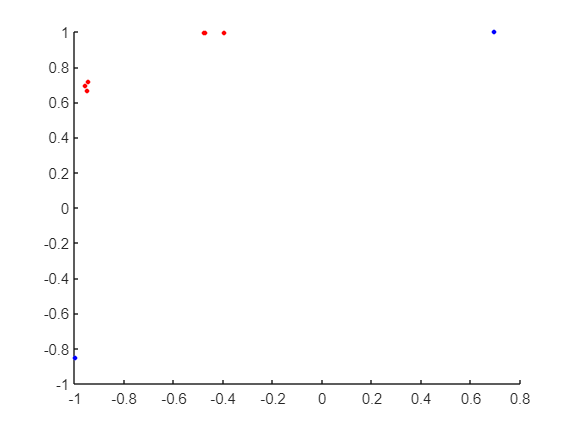

% plot
kolor = [q2.tmat,zeros(size(q2.tmat)),1-q2.tmat];
scatter(q2act1k.hid(:,1),q2act1k.hid(:,2),10,kolor,"filled")

## Q3 Repeat exercise 2 with 4 binary inputs --> target values of 0 for inputs 0000 and 1111 target 1 for all other (14) inputs.

% generate all possible combination of input 4
q3.smat = ff2n(4);
% set first (0000) and last (1111) output to 0
q3.tmat = ones(16,1);
q3.tmat(1) = 0;
q3.tmat(16) = 0;
% init 4 inputs, 2 hiddens, 1 out
q3net0 = initnet3(4,2,1,2,2,rs);

act0 = struct with fields:
    stim: [16×4 double]
     hid: [16×2 double]
     out: [16×1 double]

ans =       0.42805      0.43406
      0.23172      0.47132
       0.5298     0.062348
      0.35256      0.10888
     0.084293      0.70555
     -0.13616      0.72832
      0.21352      0.44288
   -0.0046488      0.47977
      0.64822      0.70172
      0.50107      0.72474


% train
q3net1k = bp3(q3net0,q3,1500,.5,0,rs);
% check output
q3act1k = forw3(q3net1k,q3);
q3act1k.out

ans =      0.080234
      0.99588
      0.99335
      0.99776
      0.99579
      0.99876
      0.99869
      0.98316
      0.99457
      0.99844


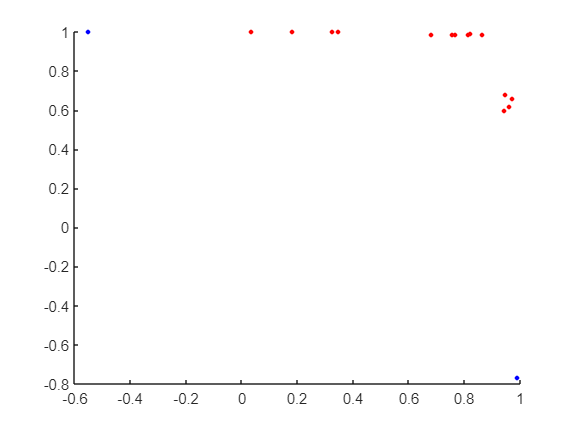

kolor = [q3.tmat,zeros(size(q3.tmat)),1-q3.tmat];
scatter(q3act1k.hid(:,1),q3act1k.hid(:,2),10,kolor,"filled")

## Q4 Train a network on the XOR task.  Plot the representations of the training set in the hidden unit space. Challenge: Create a contour plot of the output unit's response in the stimulus space.

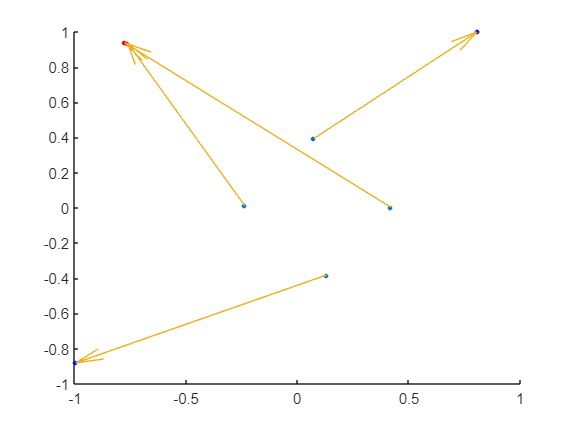

% train XOR
xor.smat = [0 0;0 1;1 0;1 1];
xor.tmat = [0 1 1 0]';
xornet0 = initnet3(2,2,1,2,2,rs);
xoract0 = forw3(xornet0,xor);
xornet1k = bp3(xornet0,xor,1000,1,0,rs);
xoract1k = forw3(xornet1k,xor);
% set color
kolor = [xor.tmat,zeros(size(xor.tmat)),1-xor.tmat];

figure
hold on
% draw training set
scatter(xoract0.hid(:,1),xoract0.hid(:,2),10,"filled")
% draw trained set
scatter(xoract1k.hid(:,1),xoract1k.hid(:,2),10,kolor,"filled")
% quivers point from untrained to trained
drawArrow = @(x1,y1,x2,y2) quiver(x1,y1,x2-x1,y2-y1,0);
drawArrow(xoract0.hid(:,1),xoract0.hid(:,2),xoract1k.hid(:,1),xoract1k.hid(:,2))
hold off

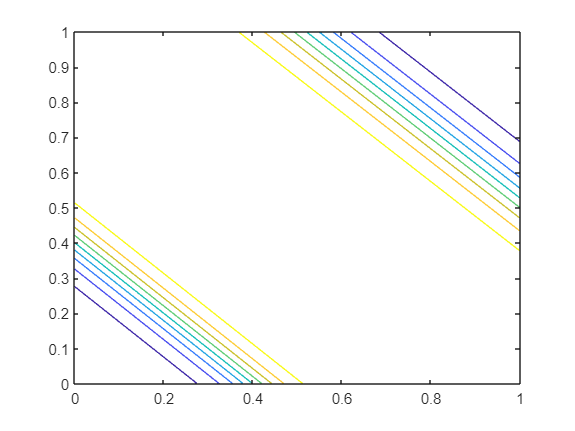


figure
% build input
x = 0:0.01:1;
y = 0:0.01:1;
% generate all [x y] combination
stims=combvec(x,y)';
% obtain output from the network
netwk=xornet1k;
hid=layersigpn(stims,netwk.wih,netwk.hbias) ;
out=layersig01(hid,netwk.whout,netwk.obias) ;
% contour input prep
[X,Y]= meshgrid(x,y);
contour(X,Y,griddata(stims(:,1),stims(:,2),out,X,Y))


% Correction: easier way using reshape()
Z = reshape(out,[length(x),length(y)])

Z =      0.008486    0.0088785    0.0093125    0.0097933     0.010327     0.010921     0.011584     0.012325     0.013155     0.014087     0.015138     0.016324     0.017668     0.019193      0.02093     0.022913     0.025184      0.02779      0.03079     0.034252     0.038257       0.0429     0.048294      0.05457     0.061884     0.070415     0.080368     0.091977       0.1055      0.12123      0.13947      0.16052      0.18468      0.21221      0.24329      0.27801       0.3163      0.35792      0.40242      0.44913      0.49724      0.54578      0.59374      0.64015      0.68417      0.72511       0.7625      0.79611      0.82586      0.85188
    0.0088795    0.0093136    0.0097946     0.010329     0.010923     0.011586     0.012327     0.013157      0.01409     0.015141     0.016327     0.017671     0.019197     0.020935     0.022919      0.02519     0.027797     0.030798     0.034261     0.038268     0.042912     0.048308     0.054587     0.061904     0.070438     0.080395     0.

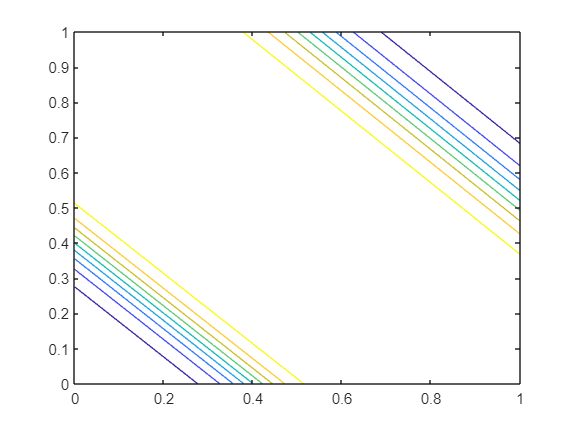

contour(X,Y,Z)

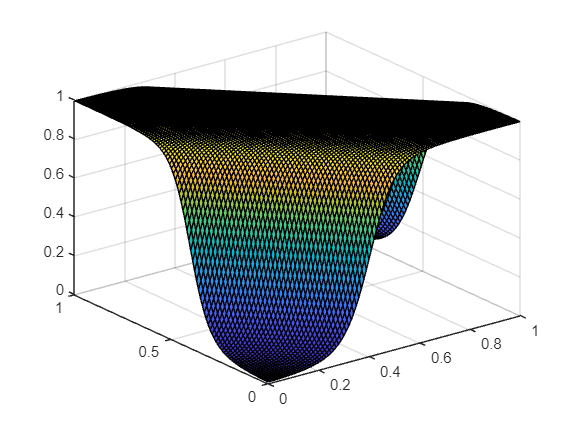

surf(X,Y,Z)

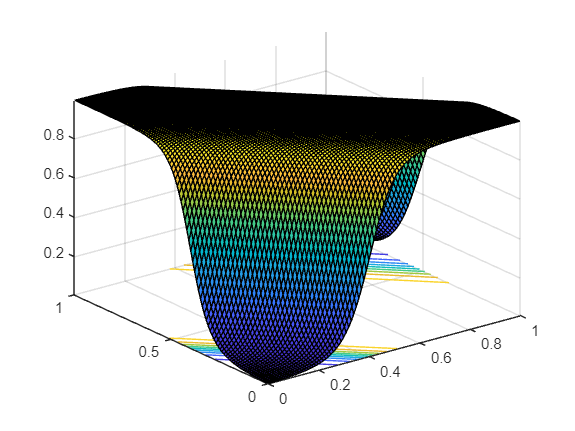

surfc(X,Y,Z)